# Distance detector

The above written code is to find the amount distance walked by the person.

load("ProjectModel.mat")
whos -file ProjectModel.mat

  Name              Size             Bytes  Class        Attributes

  Acceleration       -              204369  timetable              
  Position           -                8931  timetable              



lat=Position.latitude;
lon=Position.longitude;
positionDatetime=Position.Timestamp;

Xacc = Acceleration.X;
Yacc = Acceleration.Y;
Zacc = Acceleration.Z;
accelDatetime=Acceleration.Timestamp;

% We use the following to obtain linear time data in seconds from a datetime array
positionTime=timeElapsed(positionDatetime);
accelTime=timeElapsed(accelDatetime);
earthCirc = 24901;
totaldis = 0;
for i = 1:(length(lat)-1)
    lat1 = lat(i);     % The first latitude
    lat2 = lat(i+1);   % The second latitude
    lon1 = lon(i);     % The first longitude
    lon2 = lon(i+1); 
    degDis = distance(lat1, lon1, lat2, lon2);
    dis = (degDis/360)*earthCirc;
    totaldis = totaldis + dis;
end
stride = 2.5;                   % Average stride (ft)
totaldis_ft = totaldis*5280;    % Converting distance from miles to feet
steps = totaldis_ft/stride;
disp(['The total distance traveled is: ', num2str(totaldis),' miles'])

The total distance traveled is: 0.074323 miles


disp(['You took ', num2str(steps) ' steps'])

You took 156.971 steps


function newArray =timeElapsed(datetime_array)
    newArray=second(datetime_array);
    array_size=numel(newArray);
    first=newArray(1);
    i=1;
    while i<array_size
        if(newArray(i)>newArray(i+1))
            newArray(i+1)=newArray(i+1)+60;
            i=1;
        end
        i=i+1;
    end
    newArray=newArray-first;
end


# **Movement detector**

The acceleration of sitting, walking and Driving/Riding data is given as input and thus we can build a model which can predict the person is doing either three of the given activity.

sitAcc=load("SittingAcc.mat")

sitAcc = struct with fields:
    Acceleration: [9017×3 timetable]


walkAcc=load("walking_acc.mat")

walkAcc = struct with fields:
    Acceleration: [1815×3 timetable]


drivAcc=load("driving_acc.mat")

drivAcc = struct with fields:
    Acceleration: [3059×3 timetable]



sitLabel = 'Sitting';
sitLabel = repmat(sitLabel, size(sitAcc.Acceleration, 1), 1);
sitAcc.Acceleration.Activity = sitLabel

sitAcc = struct with fields:
    Acceleration: [9017×4 timetable]



walkLabel = 'Walking';
walkLabel = repmat(walkLabel, size(walkAcc.Acceleration, 1), 1);
walkAcc.Acceleration.Activity = walkLabel;

drivLabel = 'Running';
drivLabel = repmat(drivLabel, size(drivAcc.Acceleration, 1), 1);
drivAcc.Acceleration.Activity = drivLabel;

allAcceleration = [sitAcc.Acceleration; walkAcc.Acceleration; drivAcc.Acceleration];

allAcceleration = timetable2table(allAcceleration, "ConvertRowTimes", false)

allAcceleration = 13891×4 table
       X           Y         Z       Activity
    ________    _______    ______    ________

    -0.02595    0.10395     9.783    Sitting 
      -0.024      0.111     9.791    Sitting 
    -0.01395      0.099    9.7811    Sitting 
      -0.024    0.10095     9.788    Sitting 
    -0.01695    0.10605     9.788    Sitting 
      -0.024    0.10395     9.783    Sitting 
    -0.01695    0.10395    9.7759    Sitting 
    -0.01395    0.11295     9.783    Sitting 
    -0.01695    0.10905     9.788    Sitting 
    -0.01395    0.10095     9.791    Sitting 
      -0.012      0.111     9.786    Sitting 
    -0.01395      0.111    9.7759    Sitting 
      -0.024    0.10395    9.7759    Sitting 
    -0.01695    0.10905     9.779    Sitting 
    -0.01905    0.10095     9.779    Sitting 
      -0.024    0.10395    9.7811    Sitting 


training the model **Classification Learner.**

classificationLearner

- ** Click New session **and then select the **allAcceleration** as the parameter in the poped up window.

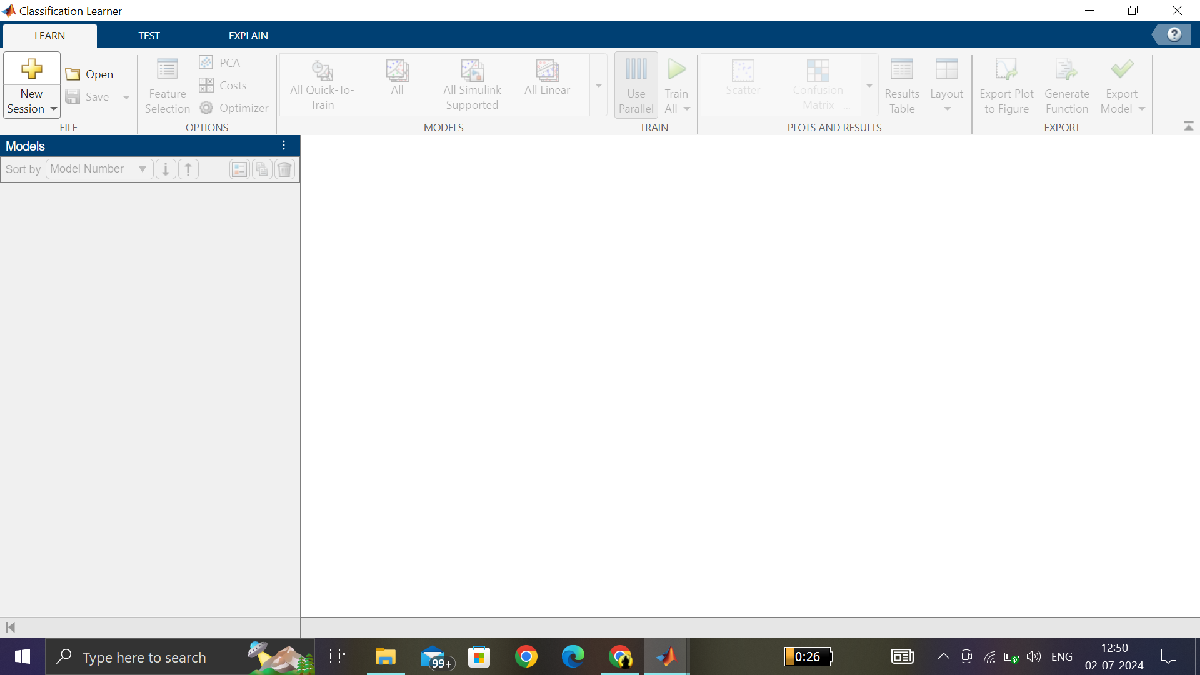

2. Then select **Start session.**

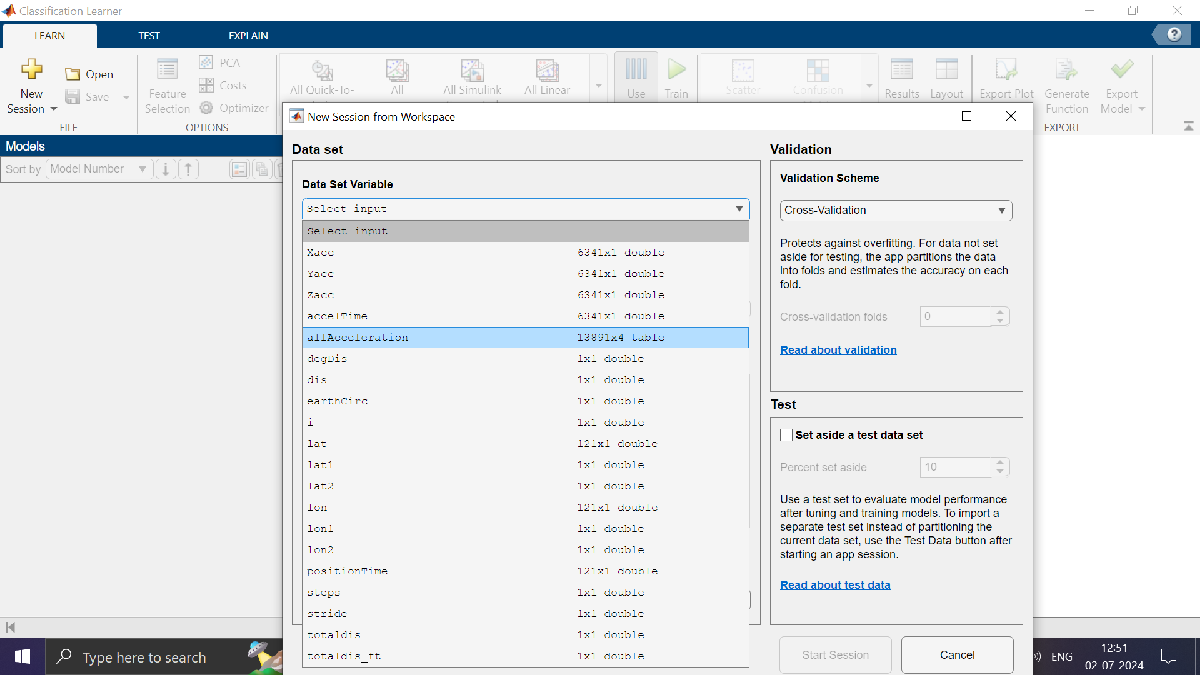

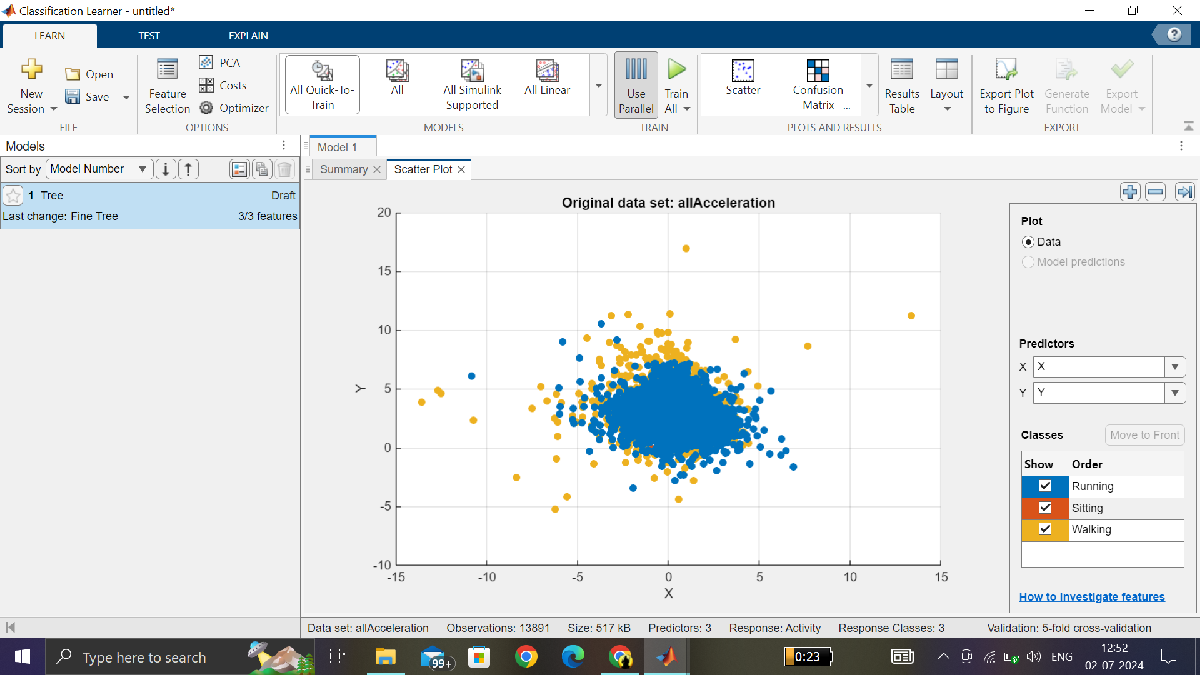

3.Select **all quick to train **and select the model 2 then click **Train this model.**

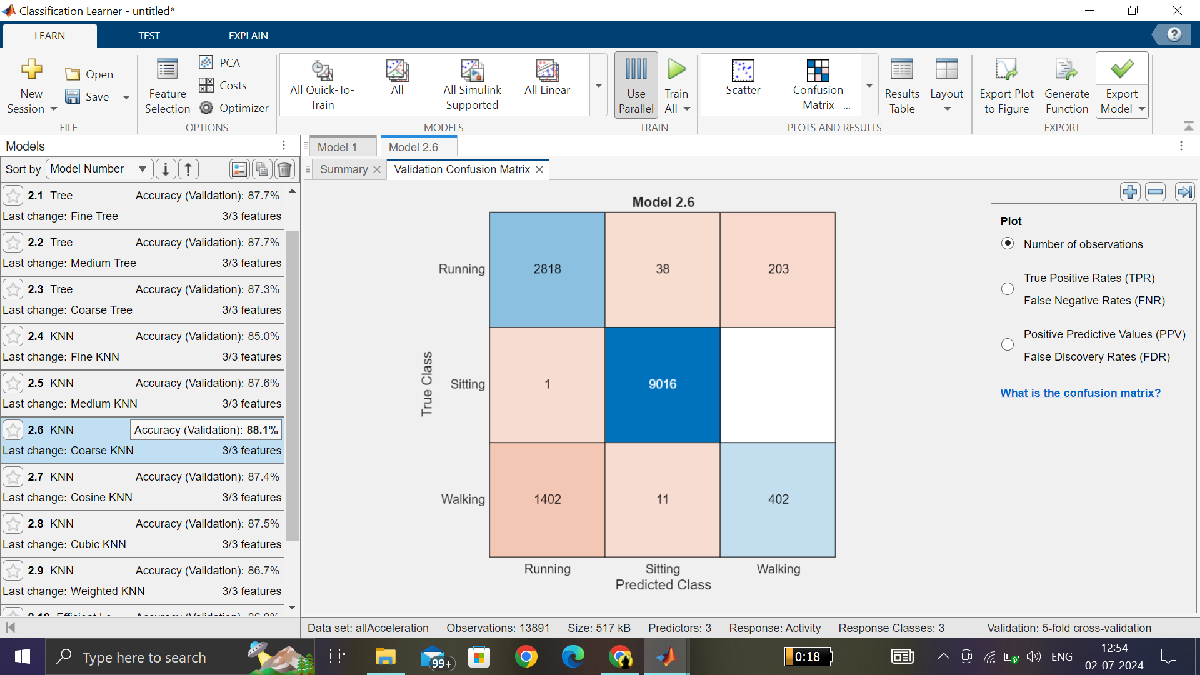

4. after selecting the model with best accuracy, click **Export model **and save it.

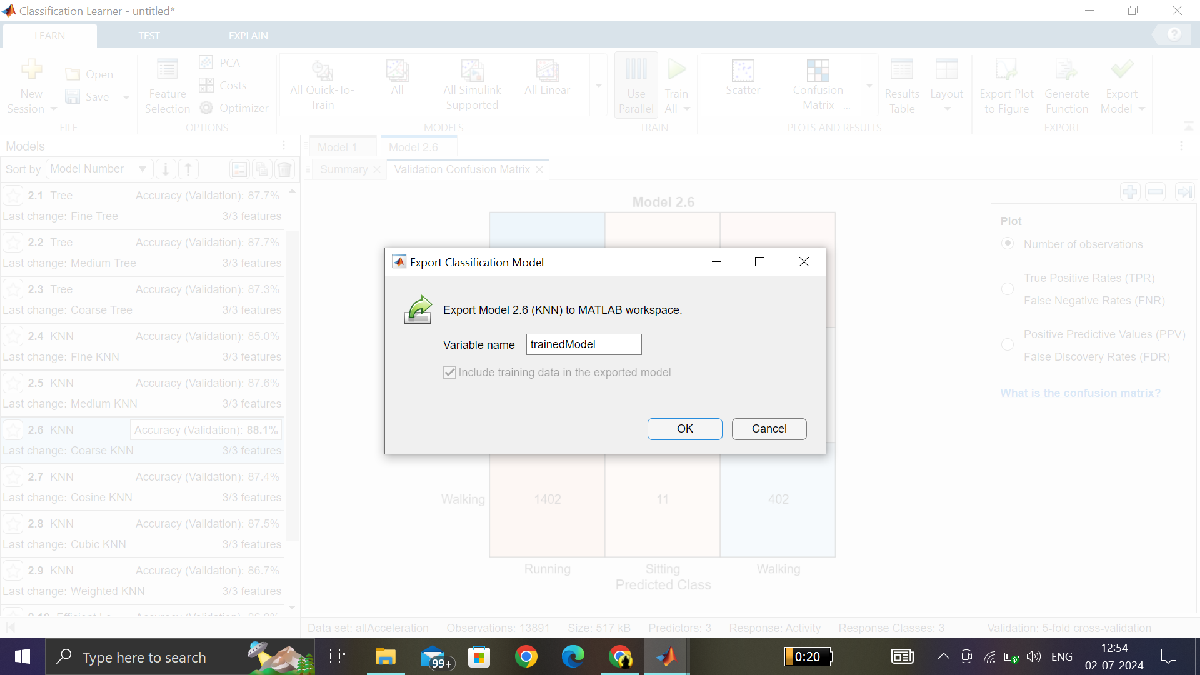

after training, testing should be done.

driv=load("driving_acc.mat")

driv = struct with fields:
    Acceleration: [3059×3 timetable]



driv.Acceleration;

justAcc = timetable2table(driv.Acceleration, "ConvertRowTimes", false);
yfit = trainedModel.predictFcn(justAcc)

yfit = 3059×7 char array
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Walking'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Running'
    'Runn

# **Plotting the data**

once the predicted data is done, the data can be plotted as graph or pie chart as done.

**Graph:**

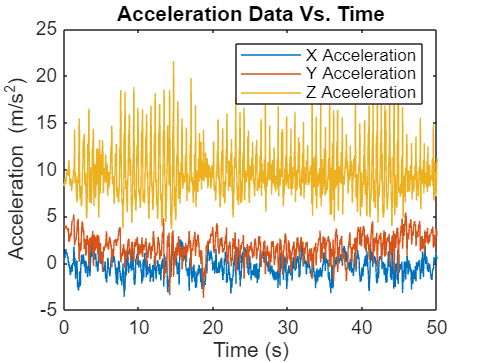

plot(accelTime,Xacc);
hold on;
plot(accelTime,Yacc); 
plot(accelTime,Zacc);
xlim([0 50])
legend('X Acceleration','Y Acceleration','Z Aceeleration');
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)');
title('Acceleration Data Vs. Time');
hold off

**Pie Chart:**

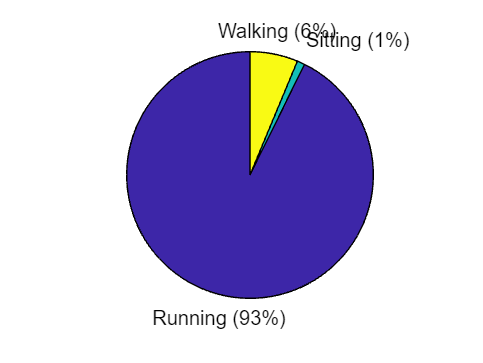

yfitcat = categorical(cellstr(yfit));
pie(yfitcat)